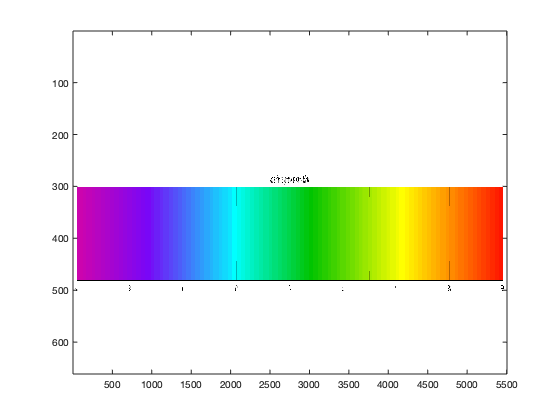

clearvars; % clear up variables and figures2.
close all;
[filename,directory] = uigetfile({'*.png'},'Select an image');
I = imread(fullfile(directory,filename));
image(I);

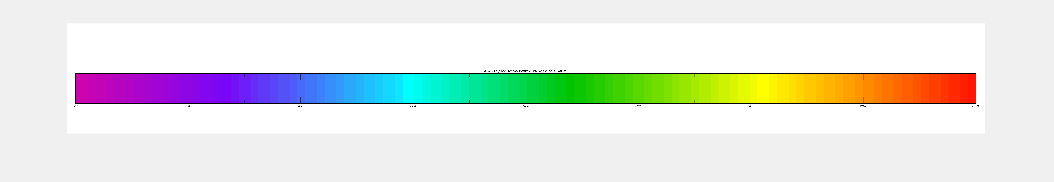

% cropping scale
J = imcrop(I);
lowestTemp = str2double(inputdlg("Enter the lowest temperature"));

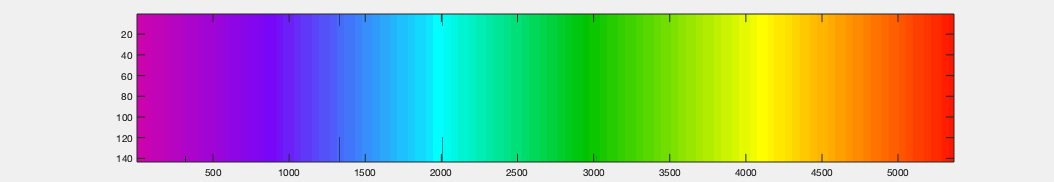

highestTemp = str2double(inputdlg("Enter the highest temperature"));
image(J)

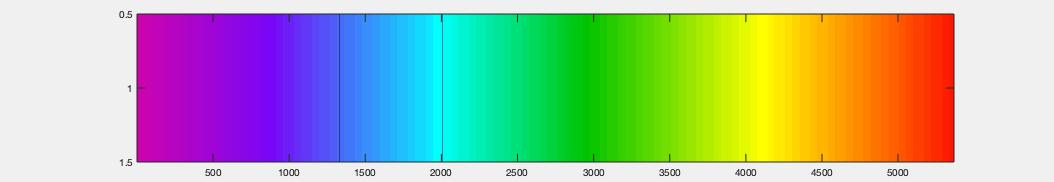

% load and process
color = J(1,:,:);
image(color)

color = reshape(color, size(color,2), 3);
color = color';
color = int16(color);

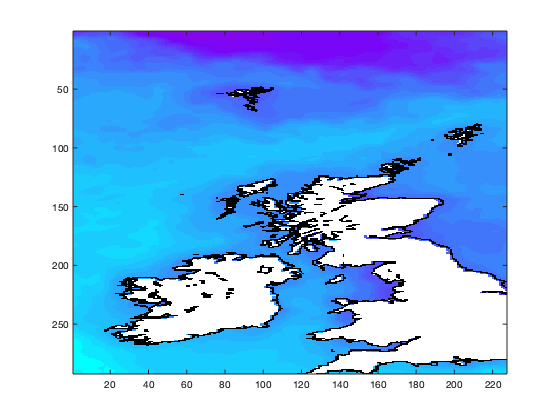

% open picture
close all
[filename,directory] = uigetfile({'*.*','*.png'},'Select an image');
map = imread(fullfile(directory,filename));
image(map)

% one input
close all
image(map);

pos = ginput(1);

Error using plotedit (line 123)
Functionality not supported with figures created with the uifigure function. For more information, see Graphics Support in App Designer.

Error in uisuspend (line 48)
            'ploteditEnable',        plotedit(fig,'getenabletools'), ...        

Error in 

pos = round(pos);
pos_rgb = map(pos(2),pos(1),:);
image(pos_rgb)
% pos_rgb = reshape(pos_rgb, 3, 1);
% pos_rgb = int16(pos_rgb);
% diff = color - pos_rgb;
% [~,] = min(sum(diff.^2,1));

[pos_temp,min_index] = getTemp(map, color, ...
                          lowestTemp, highestTemp, pos)
destinyColor = reshape(color(:,round(min_index)),[1 1 3]);
destinyColor = uint8(destinyColor);
image(destinyColor)

% multiple inputs
close all
image(map);
N = 15;
pos_list = ginput(N);
pos_temp_list = zeros(1,N);

for i = 1:N
    pos = pos_list(i,:);
    pos = round(pos);
    pos_rgb = map(pos(2),pos(1),:);
    pos_rgb = reshape(pos_rgb, 3, 1);
    pos_rgb = int16(pos_rgb);
    diff = color - pos_rgb;
    [~,min_index] = min(sum(diff.^2,1));
    pos_temp_list(i) = (highestTemp-lowestTemp)*min_index/(size(color,2))+lowestTemp;
end

mean_temp = mean(pos_temp_list)

% convert into temp matrix

latitude = [1:2:size(map,1)];
longtitude = [1:2:size(map,2)];
indexM = zeros(length(latitude),length(longtitude));
tempM = zeros(length(latitude),length(longtitude));
for i = 1:length(latitude)
    for j = 1:length(longtitude)
        [tempM(i,j),indexM(i,j)] = getTemp(map, color, lowestTemp, highestTemp, [longtitude(j), latitude(i)]);
    end
end
indexM = flipud(indexM);
tempM = flipud(tempM);
contourf(tempM,[0:0.5:30])

% Display results
clf
hold off
contourf(tempM,[0:1:40],'showText','on')
colormap default


function [temp,index] = getTemp(map, color, lowestTemp, highestTemp, pos)
    pos = round(pos);
    pos_rgb = map(pos(2),pos(1),:);
    image(pos_rgb)
    pos_rgb = reshape(pos_rgb, 3, 1);
    pos_rgb = int16(pos_rgb);
    if (norm(double(pos_rgb) - [255;255;255]) < 2) || (norm(double(pos_rgb) - [0;0;0]) < 2)
        temp= 40;
        index = 0;
    else
        diff = color - pos_rgb;
        [~,index] = min(sum(diff.^2,1));
        temp = (highestTemp-lowestTemp)*index/(size(color,2))+lowestTemp;
    end
end